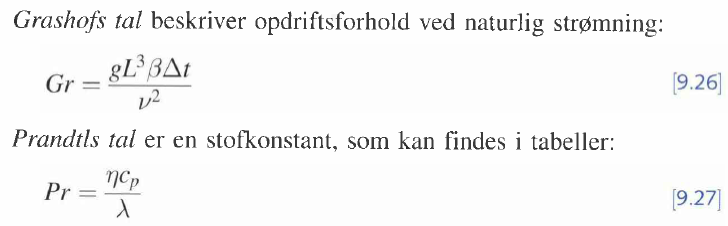

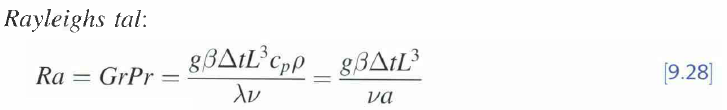

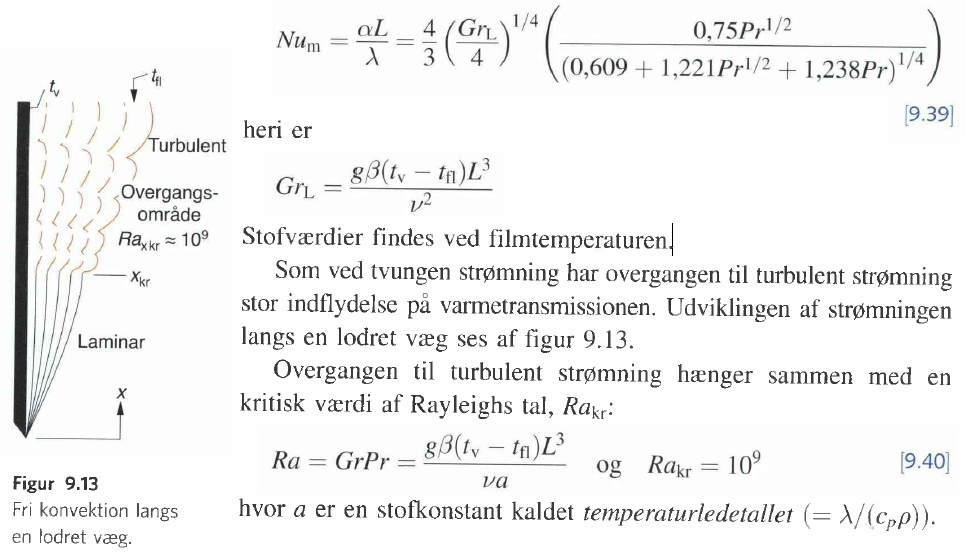

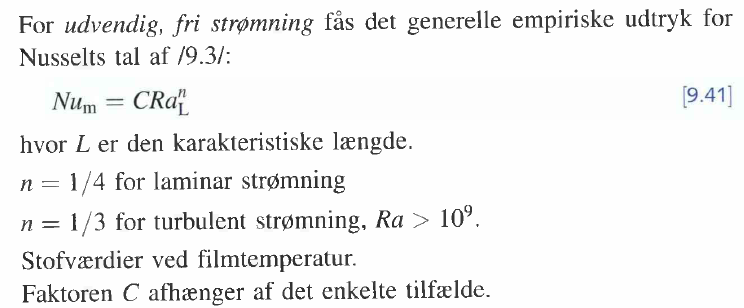

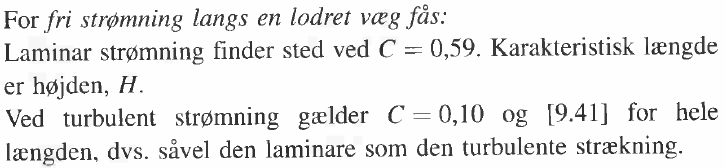

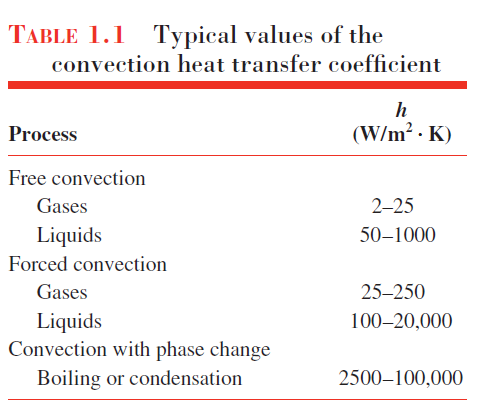

% % CP = py.importlib.import_module("CoolProp.CoolProp");
% T_luft = 20 +273.15
% T_film_fin
% g = 9.82;
% nu = 15.06e-6; % ved 20 grad
% beta = 1/T_luft
% Gr = g * beta * (t_v - t_luft)/nu^2
% Pr = eta * c_p / lambda
% 
% Ra_L = Gr * Pr
% C = 0.59;
% n = 1/4;
% Nu_m = C * Ra_L^n'


h = 10 

k = 177; %konducteviteten for alu tabel A.1
N = 66; %antal finner per side
w = 0.465; %højden af findenen
L = 0.03; %længden af finnen
T =  0.0005; % tykkelsen af finnen
h_luft = 10; %convection heat transfer coeffecient = 10  from table 1.1
L_c = L + T/2

L_c =                    0.03025


A_f = 2*w*L_c %finne arealet

A_f =                  0.0281325


A_b = 0.555*1.18 - w*T*N %arealet af basen

A_b =                   0.639555


A_t = N*A_f + A_b %total areal

A_t =                     2.4963


A_c = w*T

A_c =                  0.0002325


P = 2*w + 2*T

P =                      0.931


m = sqrt(h_luft*P/(k*A_c))

m =           15.0410006039402



% R_conv = 1/(h_vand * A_vand)

% R_cond = 1/(k*A_wall)

eta_f = tanh(m*L_c) / (m*L_c)

eta_f =          0.936266969927751


eta_0 = 1 - (N  * A_f) / A_t * (1 - eta_f)

eta_0 =          0.952595447293395


A_t = N*A_f + A_b

A_t =                     2.4963


R_finner = 1/(eta_0 * h_luft * A_t)

R_finner =          0.042052781020195




% R_tot = R_conv + R_cond + R_finner